## Problem 0

load('Homework.mat')

## Problem 1

% define
n = size(data1,1)

n = 1000

numboots = 500;   % number of bootstraps to perform
size_of_regressors = size(regressors1,2)

size_of_regressors = 100

bunch_of_sample = 500

bunch_of_sample = 500

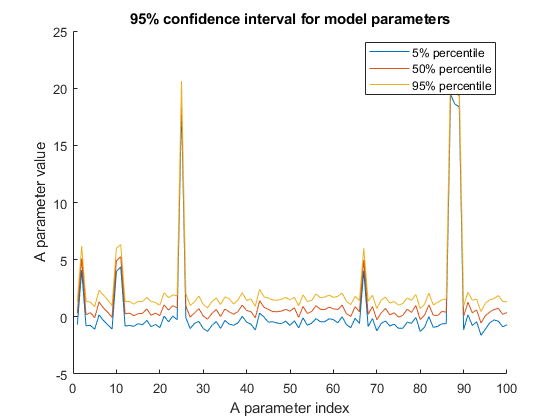


% perform the bootstraps
modelfit = zeros(numboots, length(data1));
params = zeros(numboots, size_of_regressors);

for boot=1:numboots
    
    % Prepare data indices
    ix = ceil(n*rand(1,bunch_of_sample));
    % Construct regressor matrix
    X = regressors1(ix,:);
    % Estimate parameters
    h = (X' * X) \ X'*data1(ix);
    % Record the parameters
    params(boot,:) = h;
end

% Summarizing bootstrap results via percentiles
paramsP = prctile(params,[2.5 50 97.5],1);

% visualize
figure;
hold on;
xlabel('A parameter index')
ylabel('A parameter value')
a = plot(paramsP(1,:));
b = plot(paramsP(2,:));
c = plot(paramsP(3,:));

legend([a b c], '5% percentile', '50% percentile', '95% percentile');
title('95% confidence interval for model parameters');

## Problem 2

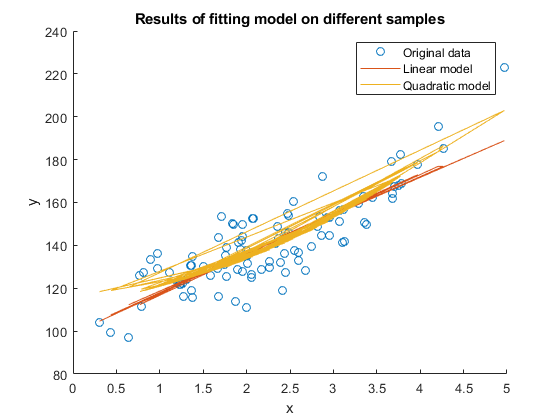

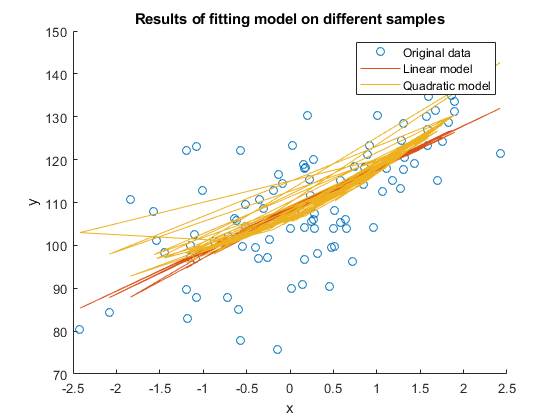

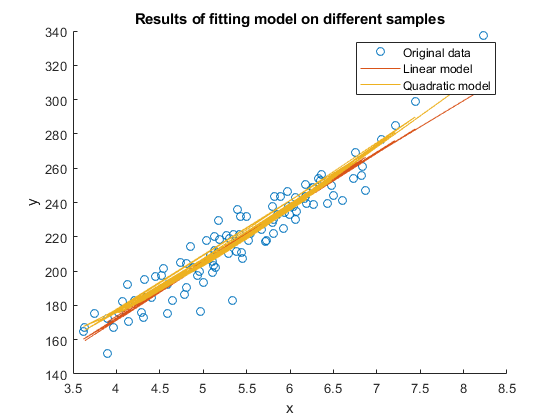

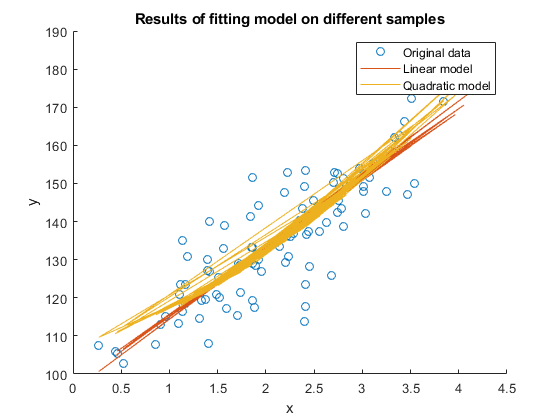

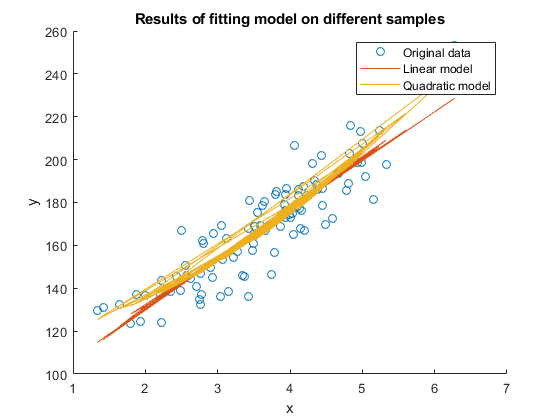

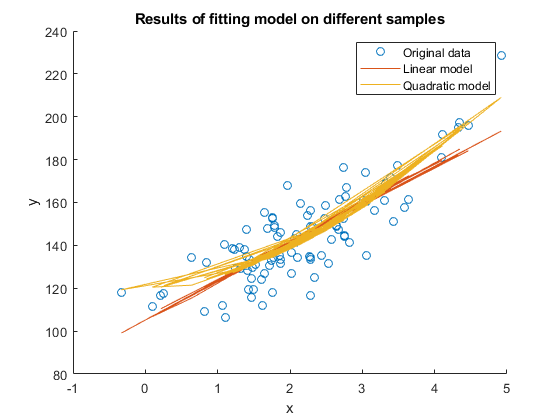

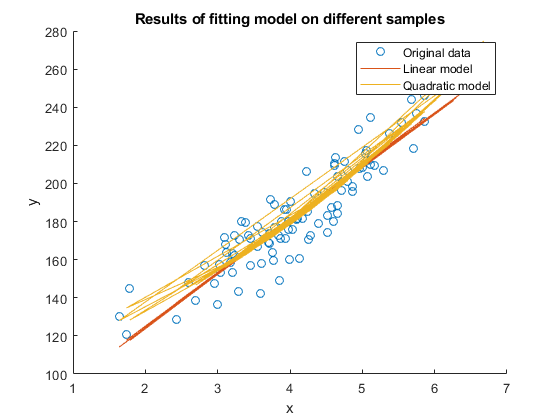

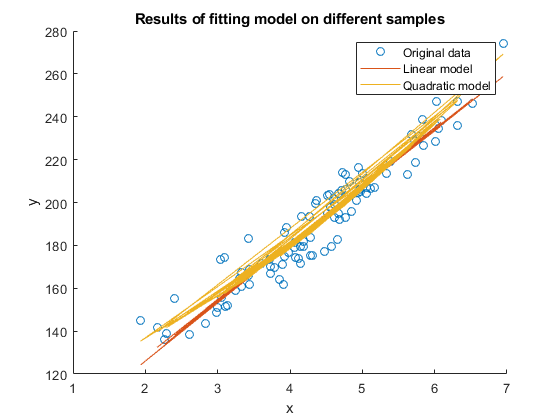

% We should check if we have the linear or quadratic dependency between the
% X and Y value in our measurments. In order to do this, we will use the
% 10-fold cross validation to to estimate the accuracy of both models and
% then, apply the R^2 to quantify the accuracy
 
numfolds = 10;  % number of folds to use in cross-validation

% calculate some quantities (to make the code general) 
numsubjects = size(xdata,2); 
numdatapoints = size(xdata,1);

% generate a random split of the data points into parts. 
% allix is a 2D matrix of indices, with dimensions [parts] x [indices]. 
allix = randperm(numdatapoints);           % all data indices, randomly ordered 
numineach = ceil(numdatapoints/numfolds);  

% at least one part must have this many data points 
allix = reshape([allix NaN(1,numfolds*numineach-numdatapoints)],numfolds,numineach);

% define a R^2 function 
computeR2 = @(model,data) 100 * (1 - sum((data-model).^2) / sum((data-mean(data)).^2));

% initialize 
R2_linear = zeros(1,numsubjects); 
R2_quadratic = zeros(1,numsubjects);
% analyze each subject 
for subject=1:numsubjects
    
  % perform k-fold cross-validation  
  prediction_linear = zeros(numdatapoints,1);
  prediction_quadratic = zeros(numdatapoints,1);
  for fold=1:numfolds
      
    % figure out data indices
    testix = allix(fold,:);  % indices to use for testing    
    testix(isnan(testix)) = [];  % remove NaNs if necessary    
    trainix = setdiff(1:numdatapoints,testix);  % indices to use for training
    
    % prepare regressor matrices and data    
    Xtrain = [xdata(trainix,subject) ones(length(trainix),1)];    
    Xtest =  [xdata(testix,subject) ones(length(testix),1)];    
    ytrain = ydata(trainix,subject);    
    ytest =  ydata(testix,subject);
    
    % train and test linear model    
    h = (Xtrain'*Xtrain)\Xtrain'*ytrain;    
    prediction_linear(testix) = Xtest*h;
    
    % prepare regressor matrices and data    
    Xtrain = [xdata(trainix,subject).^2 xdata(trainix,subject) ones(length(trainix),1)];    
    Xtest =  [xdata(testix,subject).^2 xdata(testix,subject) ones(length(testix),1)];    
    ytrain = ydata(trainix,subject);    ytest =  ydata(testix,subject);
    
    % train and test quadratic model    
    h = inv(Xtrain'*Xtrain)*Xtrain'*ytrain;    
    prediction_quadratic(testix) = Xtest*h;
  end
  
  % quantify accuracy  
  R2_linear(subject)    = computeR2(prediction_linear,   ydata(:,subject));  
  R2_quadratic(subject) = computeR2(prediction_quadratic,ydata(:,subject));
  
  % Plot the received data
  figure;
  hold on;
  xlabel('x');
  ylabel('y');
  title('Results of fitting model on different samples')
  % Make a scatter plot of matrix elements
  h1 = scatter(xdata(:,subject),ydata(:,subject));
%   Plot the regression lines
  h2 = plot(xdata(:,subject), prediction_linear);
  h3 = plot(xdata(:,subject), prediction_quadratic);
  uistack(h2,'top')
  uistack(h3, 'top')
    
  legend([h1, h2, h3], 'Original data', 'Linear model', 'Quadratic model')
end

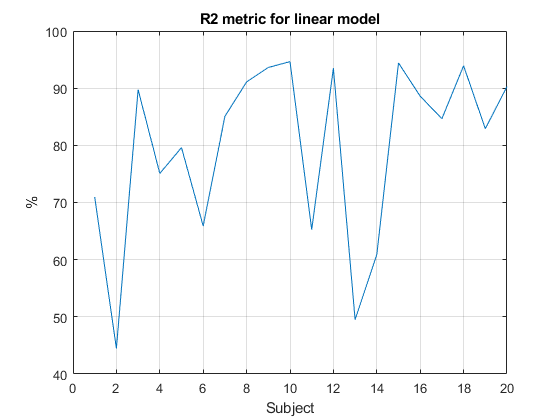




% visualize the R2 dependency for each subject
figure;
plot(R2_linear); 
grid;
title('R2 metric for linear model')
xlabel('Subject');
ylabel('%')

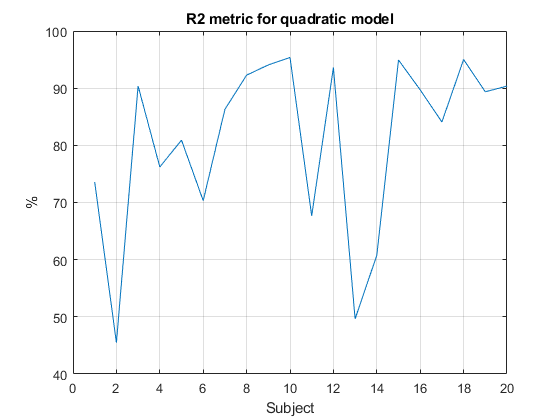


plot(R2_quadratic); 
grid;
title('R2 metric for quadratic model')
xlabel('Subject');
ylabel('%')

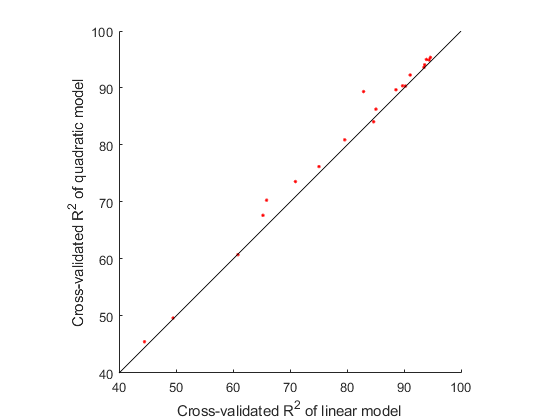


% visualize 
figure; 
hold on; 
scatter(R2_linear,R2_quadratic,'r.'); 
axis equal square; ax = axis; 
plot(ax(1:2),ax(1:2),'k-'); 
xlabel('Cross-validated R^2 of linear model'); 
ylabel('Cross-validated R^2 of quadratic model');

% Summary: If we look at the scatter plot, we can notice that the
% model can be considered as quite accurate, while using both linear and quadratic
% functions